% Load data
clear; clc;
% Helper functions' path
addpath('geodesy');
addpath('src')

load(".results/20201119T111132_fractions_1.00_1.00_dump1090.mat");
% Removing sensors
idx = result(:,6) == 0;
unknown(idx,:) = [];
result(idx,:) = [];
measurement_count(idx,:) = [];
unknown.meas_count = measurement_count;

% Let's calculate errors
senval = table2array(unknown(:,{'x','y','z'}));

% Results
rmse = zeros(length(fractions),1);
rmse_2d = rmse;
dist3d = zeros(height(unknown),length(fractions));
dist = dist3d;

for ii = 1:length(fractions)
    resval = result(:,1:3,ii);
    
    % 3D error
    errors = resval(:,1:3) - senval;
    dist3d(:,ii) = sqrt(sum(errors.^2,2));
    
    rmse(ii) = sqrt(median(dist3d(:,ii).^2));
    
    % Compute the 2D distance
    unknownllh = ecef2llh(resval(:,1:3) + center);
    realposllh = table2array(unknown(:, {'latitude','longitude','height'}));
    
    dist(:,ii) = havdist(unknownllh, realposllh);
    rmse_2d(ii) = sqrt(median(dist(:,ii).^2));
end

unknown.dist = dist;

% Data from Matthias
real_serials = readtable('../datasets/round_2/sensor_positions.csv');
dump1090_real = real_serials(strcmp(real_serials.type,'dump1090'),:);

% Ranking of sensors
ranking = readtable('../datasets/round_2/ranking.csv');

% Remove sensors not on ranking
mask = ismember(dump1090_real.serial, ranking.serial);

unknown_real = dump1090_real(mask,:);

llh_selected = table2array(unknown(:,{'latitude','longitude','height'}));
llh_real = table2array(unknown_real(:,{'latitude','longitude','height'}));

unknown.real_serial = zeros(height(unknown),1);
for ii = 1:size(llh_selected,1)
    dist = havdist(llh_selected(ii,:).*ones(height(unknown_real),3),llh_real);
    [~,index] = min(dist);
    mind(ii) = dist(index);
    if abs(dist(index)) < 1e-3
        unknown.real_serial(ii) = unknown_real.serial(index);
    end
end

idfilter = unknown.real_serial == 0;
candidates = unknown(~idfilter,:);

% bottom-left: 51.05587803745959, -1.2178423188782597
% top-right: 53.01010568252769, 1.218480756954651

maskreg = (candidates.latitude > 51.05587803745959 & candidates.latitude < 53.01010568252769) ...
        & (candidates.longitude > -1.2178423188782597 & candidates.longitude < 1.218480756954651);
selected1 = candidates(maskreg,:);

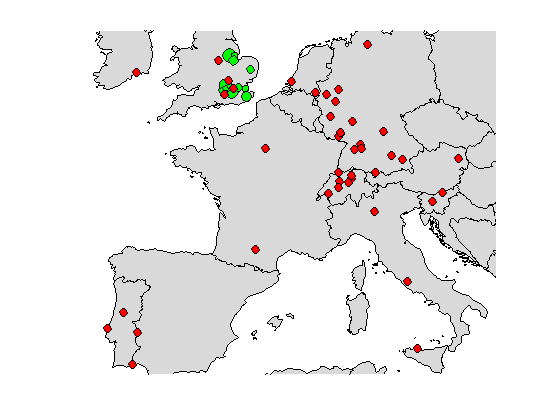

% Some plotting
% prepare the map
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
% plot good sensor locations (green dots)
scatterm(selected1.latitude, selected1.longitude, 100.*selected1.meas_count/max(selected1.meas_count), 'green', 'filled','MarkerEdgeColor',[0 0 0]);
scatterm(reference.latitude, reference.longitude,[],'red','filled','MarkerEdgeColor',[0 0 0]);

% bottom-left: 47.330745894907864, 6.150176592794725
% bottom-right: 47.330745894907864, 13.430650813558568
% top-right: 50.78333627239965, 13.430650813558568
% top-left: 50.78333627239965, 6.150176592794725

maskreg = (candidates.latitude > 47.330745894907864 & candidates.latitude < 50.78333627239965) ...
        & (candidates.longitude > 6.150176592794725 & candidates.longitude < 13.430650813558568);
selected2 = candidates(maskreg,:);

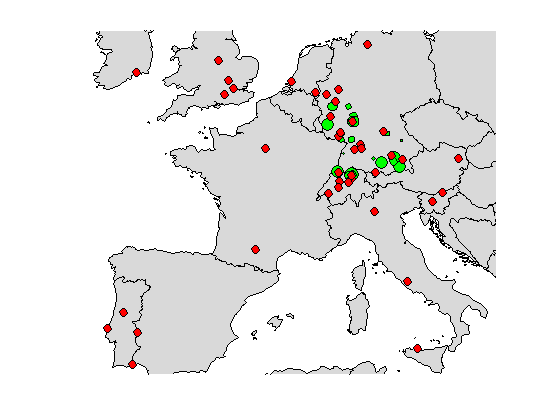

% Some plotting
% prepare the map
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
% plot good sensor locations (green dots)
scatterm(selected2.latitude, selected2.longitude, 100.*selected2.meas_count/max(selected2.meas_count), 'green', 'filled','MarkerEdgeColor',[0 0 0]);
scatterm(reference.latitude, reference.longitude,[],'red','filled','MarkerEdgeColor',[0 0 0]);

selected_csv = [selected1; selected2];
selected_csv = selected_csv(:,{'serial','real_serial','latitude','longitude','height'});